# MUSI 6202: Final Denoising Project

## Baseline System Overview

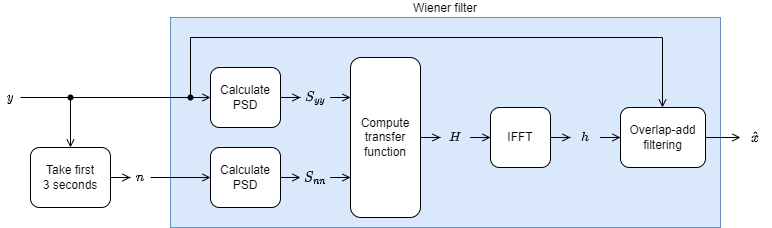

The baseline system is a simple Wiener filter with the noise profile drawing from the first 3 seconds of the noisy signal. The Wiener transfer function were computed in frequency domain from the estimated power spectral densities, then converted back to the time domain. The final filtering was done in the time-domain using overlap-add filtering.

In your 'main.mlx' file, include at the start

- A system diagram showing a high-level overview of major steps in your system;

- A brief (~100 words) description of your system;

- A list of MATLAB toolbox dependencies used (if any); and

- A list of IEEE-formatted citations for any paper or repositories used as references for your system implementation (if any). Include DOI or URL if available.

- A detailed breakdown of individual contributions to the project.

## System diagram

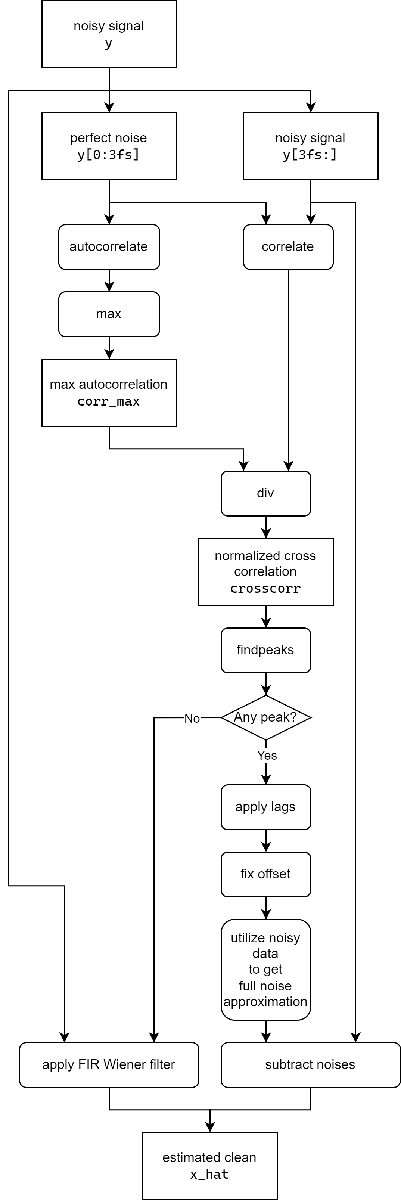

## Brief (~100 words) description of the system

Our system uses the information of the first 3 seconds of perfect noise and tries to find all occurrences of this noise in the rest of the audio file. If there's a peak in the cross-correlation curve that's significant enough, it would be considered an occurrence. The position information of these peaks would later be used to subtract noise from the noisy signal. If no occurrence is found, a normal FIR wiener filter would be applied to perform regular denoising. Furthermore, we use the peak position information and the distances between the peaks to estimate the the period of the noise, and then use the average of the noisy clips to get an approximation of the remaining part of the noise (i.e. the noise part after 3s).

## Breakdown of contributions

- Josh: Researched and tested various denoising algorithms, implemented, debugged, and optimized FIR wiener filter, improved cross correlation algorithm, wrote summary

- Michael: Researched and tested various denoising algorithms, implemented and debugged cross correlation algorithm, debugged FIR wiener filter

- Xinyu: Found bug in & debugged and improved cross correlation algorithm’s min delta SNR and median SNR, profiled code, plotted system diagram

- Bowen: Researched, experimented with possible solutions to utilize repetitive noise information in the noisy data, helped in improving SNR

addpath(genpath("./src"));

## Evaluation on the development set

devDataPath = "./data/dev";

if ismac
    devDataFolders = dir(devDataPath);
    devDataFolders = devDataFolders(3:end);
elseif ispc
    devDataFolders = ls(devDataPath);
    devDataFolders = devDataFolders(3:end, :);
end

nDevSamples = size(devDataFolders, 1);

initSnr = NaN(nDevSamples, 1);
finalSnr = NaN(nDevSamples, 1);

for i = 1:nDevSamples
    if ispc
        noisyFile = fullfile(devDataPath, devDataFolders(i, :), "noisy.wav");
        cleanFile = fullfile(devDataPath, devDataFolders(i, :), "clean.wav");
    elseif ismac
        noisyFile = fullfile(devDataPath, devDataFolders(i).name, "noisy.wav");
        cleanFile = fullfile(devDataPath, devDataFolders(i).name, "clean.wav");
    end

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);
    
    assert(fs == fsc);

    estimSig = denoise(noisySig, fs);

    % audiowrite(".\estim.wav", estimSig, fs);
    
    initSnr(i) = computeSnr(cleanSig, noisySig);
    finalSnr(i) = computeSnr(cleanSig, estimSig);
end

deltaSnr = finalSnr - initSnr;

### Result statistics

fprintf("Input SNR (dB)");

Input SNR (dB)

descStats(initSnr);

min    	median 	mean   	max    	std    
-11.90	1.54	0.43	10.92	6.71



fprintf("Output SNR (dB)");

Output SNR (dB)

descStats(finalSnr);

min    	median 	mean   	max    	std    
-5.58	10.49	10.20	14.27	1.86



fprintf("Change in SNR (dB)");

Change in SNR (dB)

descStats(deltaSnr);

min    	median 	mean   	max    	std    
-2.44	9.03	9.76	23.89	6.80


### Visualizing results

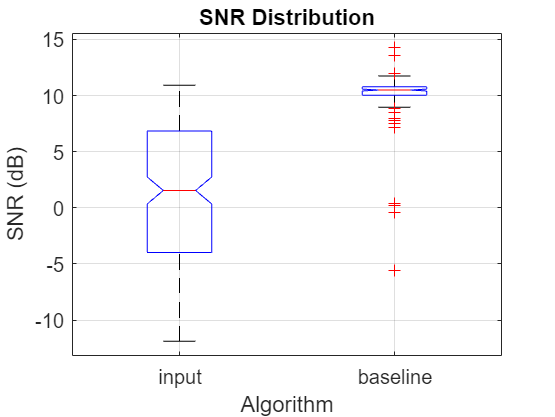

figure;
boxplot([initSnr, finalSnr], ...
    'Notch', 'on', ...
    'Labels', ["input", "baseline"] ...
);
title("SNR Distribution");
xlabel("Algorithm");
ylabel("SNR (dB)");
grid;

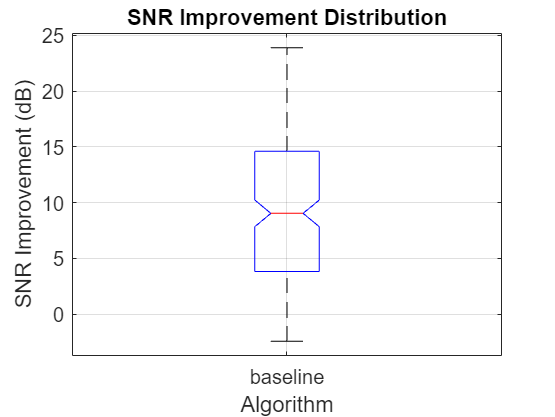

figure;
boxplot(deltaSnr, ...
    'Notch', 'on', ...
    'Labels', "baseline" ...
);
title("SNR Improvement Distribution");
xlabel("Algorithm");
ylabel("SNR Improvement (dB)");
grid;

## Profiling

profile clear

nProfileSamples = 10;

profile on
for i = 1:nProfileSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i, :), "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i, :), "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);
    
    estimSig = denoise(noisySig, fs);
end
profile off

p = profile('info');
profsave(p, "./doc/profile");

profile viewer;